HarfRateIdealdelta = calcIdealdelta(HarfRateMatrix)

%  ans = calcIntegralSameRate(FTRateMatrix,plotFTRate,FTtheorval,plotFTIdealRate)
%  plotRgraf(ans)
%  T = calcIntegral(plotDataTable,theoreticalvalue,plotIdealTable)
% buff = T(6)
% T(6) = T(3)
% buff2 = T(5)
% T(5) = buff
% T(3) = T(2)
% T(2) = T(1)
% T(1) = T(4)
% T(4) = buff2
% T = struct2table(T)
T = table2struct(T)

T = フィールドをもつ 7×1 の struct 配列:
    name
    integralvalue
    theoreticalvalue
    idealcalvalue
    inte_theoratio
    inte_idealratio


T(1) = T(5)

T = フィールドをもつ 7×1 の struct 配列:
    name
    integralvalue
    theoreticalvalue
    idealcalvalue
    inte_theoratio
    inte_idealratio


buff = T(2)

buff = フィールドをもつ struct :
                name: 'Haming74'
       integralvalue: 0.3178
    theoreticalvalue: 0.3367
       idealcalvalue: 0.3214
      inte_theoratio: 0.9439
     inte_idealratio: 0.9889


T(2) = T(3)

T = フィールドをもつ 7×1 の struct 配列:
    name
    integralvalue
    theoreticalvalue
    idealcalvalue
    inte_theoratio
    inte_idealratio


T(3) = T(4)

T = フィールドをもつ 7×1 の struct 配列:
    name
    integralvalue
    theoreticalvalue
    idealcalvalue
    inte_theoratio
    inte_idealratio


T(4) = buff

T = フィールドをもつ 7×1 の struct 配列:
    name
    integralvalue
    theoreticalvalue
    idealcalvalue
    inte_theoratio
    inte_idealratio


T(5) = T(6)

T = フィールドをもつ 7×1 の struct 配列:
    name
    integralvalue
    theoreticalvalue
    idealcalvalue
    inte_theoratio
    inte_idealratio


T(6) = T(7)

T = フィールドをもつ 7×1 の struct 配列:
    name
    integralvalue
    theoreticalvalue
    idealcalvalue
    inte_theoratio
    inte_idealratio


T = struct2table(T)

T = 7×6 table
        name        integralvalue    theoreticalvalue    idealcalvalue    inte_theoratio    inte_idealratio
    ____________    _____________    ________________    _____________    ______________    _______________

    'Lin103'           0.43396             0.455            0.44545          0.95375            0.97421    
    'ExHaming84'       0.35833             0.375             0.3611          0.95553            0.99231    
    'Lin95'            0.32892           0.34567            0.33333          0.95154            0.98677    
    'Haming74'         0.31785           0.33673            0.32142          0.94393            0.98889    
    'Haming1511'       0.22253            0.2311            0.22499          0.96294            0.98908    
    'Lin2016'          0.17395              0.18            0.17618          0.96637            0.98731    
    'Lin2016'          0.17395              0.18            0.17618          0.96637            0.98731    


hold on
 xlabel('n','FontSize',20);
 B = [6 7 8 9 10 15 20]'

B =      6
     7
     8
     9
    10
    15
    20


 NM = [0.7 0.5 (4/9) (3/7) (4/15) 0.2]'

NM =     0.7000
    0.5000
    0.4444
    0.4286
    0.2667
    0.2000


 %x軸にセルの１列目を、それ以外をy軸にそれぞれ使用してグラフを作成
 c = categorical({'Lin(6,3)','Ham(7,3)','ExHam(8,4)','Lin(9,4)','Lin(10,7)','Lin(15,4)','Lin(20,4)'})

c = 1×7 の categorical 配列
     Lin(6,3)      Ham(7,3)      ExHam(8,4)      Lin(9,4)      Lin(10,7)      Lin(15,4)      Lin(20,4) 


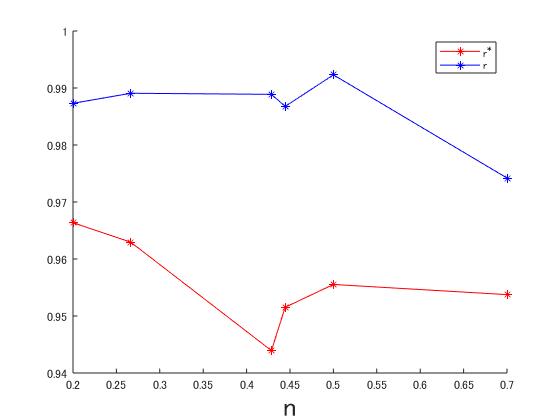

     plot(NM,T{1:6,5},'r*-');
     plot(NM,T{1:6,6},'b*-');
     legend('r^*','r');

 hold off

strage = struct('avrdelta',[],'mindelta',[],'minmatrix',[]);

strage = randammatrix(12,6)